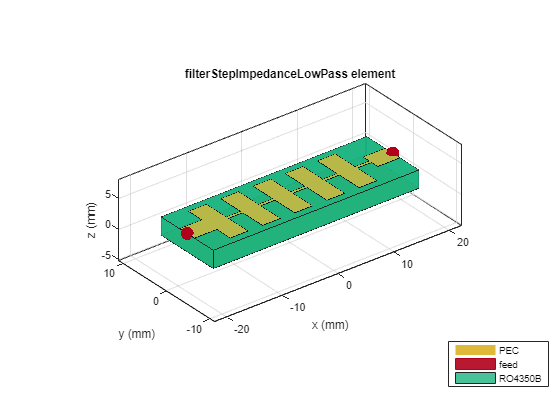

sub = dielectric("RO4350B"); 
sub.Thickness =[0.003];
steppedfilter = filterStepImpedanceLowPass;
steppedfilter.Height = 0.003;
steppedfilter.Substrate = sub;
steppedfilter.FilterOrder = 10;
figure
show(steppedfilter)

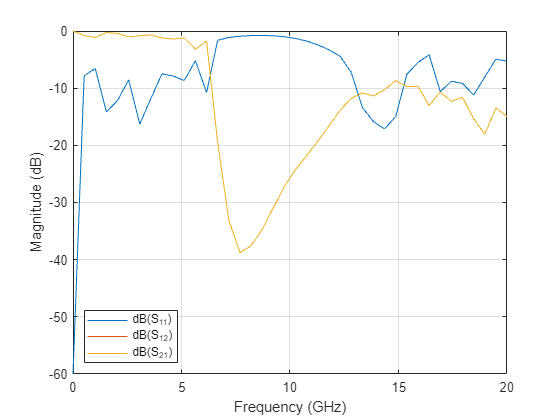

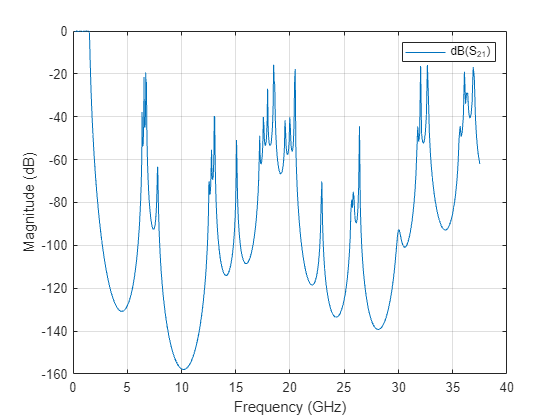

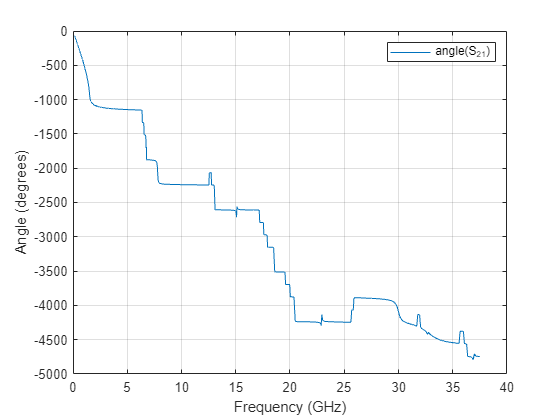


spar1 = sparameters(steppedfilter,linspace(1e6,20e9,40));
figure
rfplot(spar1,1);
legend(Location="southwest")

S-param filter viewing:

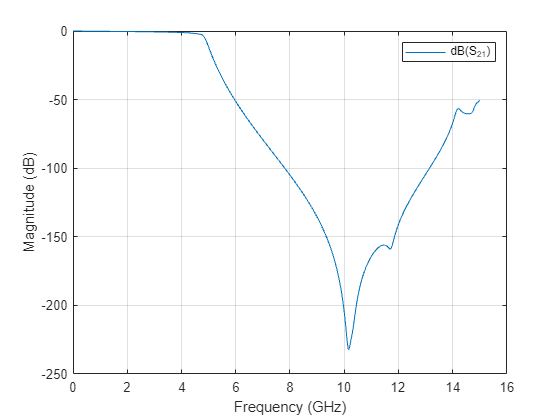

S = sparameters('filthigh5MF.s2p');
rfplot(S, 2, 1)

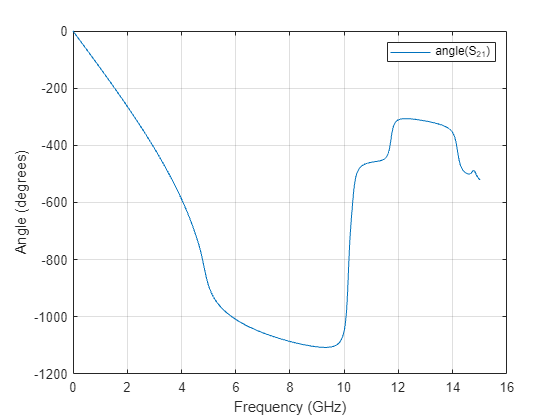

%xlim(0, 20e9)
%[hline, haxes] = rfplot(S, 2, 1, logspace(0, 20e9, 200))
rfplot(S, 2, 1, 'angle')

Generating filters:

sifilter = filterStepImpedanceLowPass(FilterOrder=11,Height=0.508e-3) ;
sub = dielectric("RO4350B");
sifilter.Substrate = sub;
sifilterobj = design(sifilter,1.5e9,Z0=50,LowZ=10,HighZ=110);
show(sifilterobj);


spar1 = sparameters(sifilter,linspace(1e6,20e9,200));
figure
rfplot(spar1, 2, 1);
legend(Location="southwest")

Manual filter test

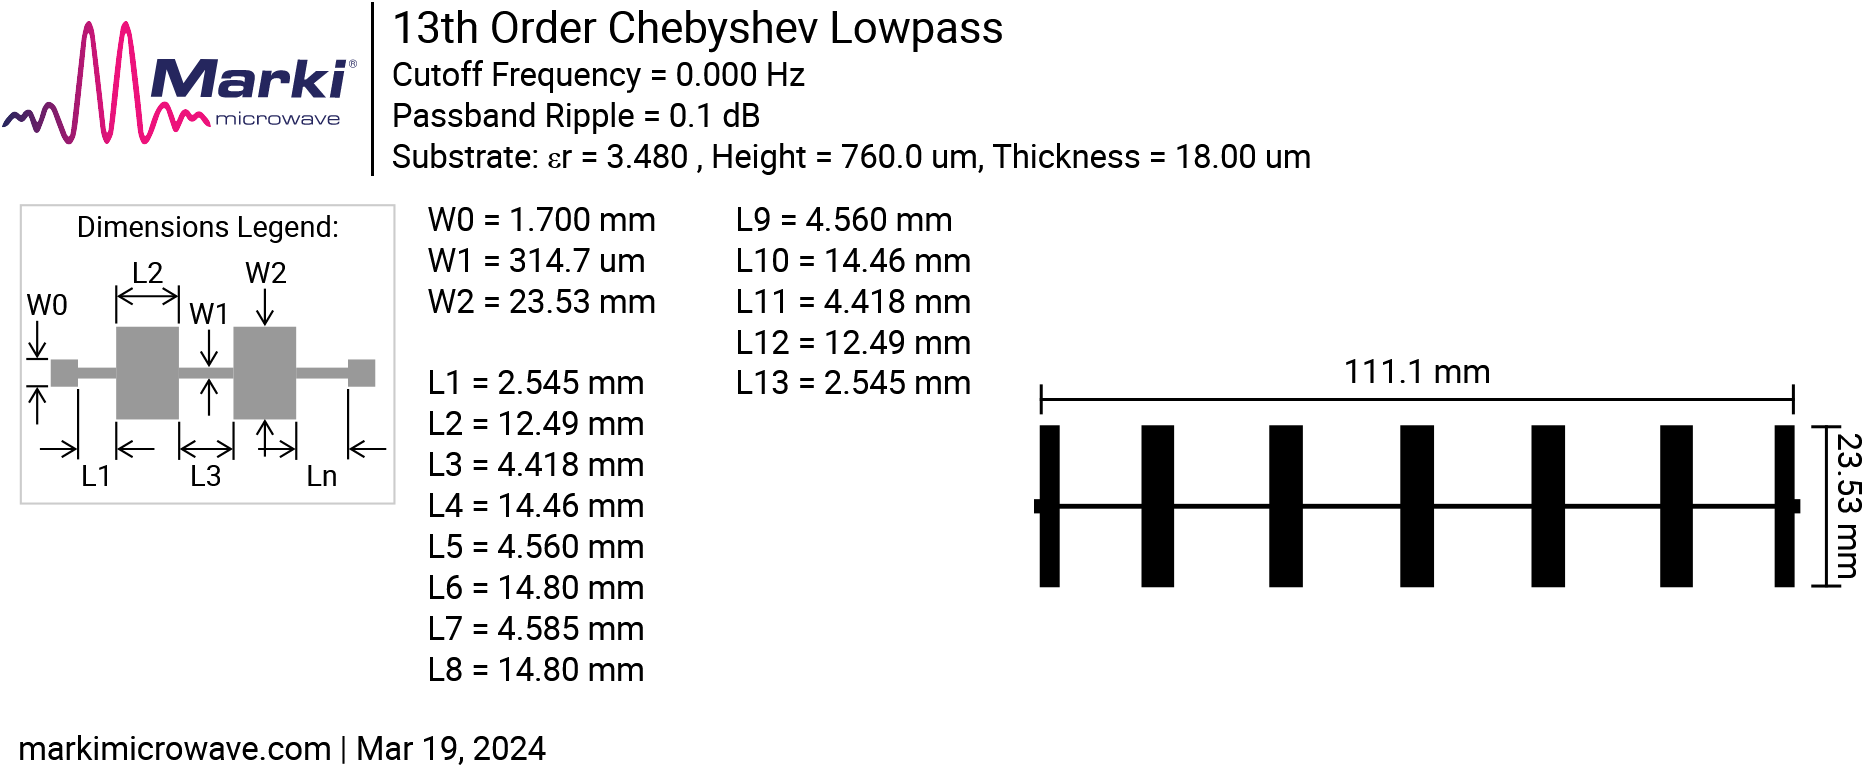

clc
clear all
close all

% Measurements in mm
W0 = 1.700;
W1 = 314.7e-3;
W2 = 23.53;

% Meas in mm
LMS = 5; % 50ohm microstrip length

L1 = 2.545;
L2 = 12.49;
L3 = 4.418;
L4 = 14.46;
L5 = 4.560;
L6 = 14.80;
L7 = 4.585;
L8 = 14.80;
L9 = 4.560;
L10 = 14.46;
L11 = 4.418;
L12 = 12.49;
L13 = 2.545;

% In m
lengths = [LMS, L1, L2, L3, L4, L5, L6, L7, L8, L9, L10, L11, L12, L13, LMS] * 1e-3;
L_tot = sum(lengths);
W_tot = 30e-3;

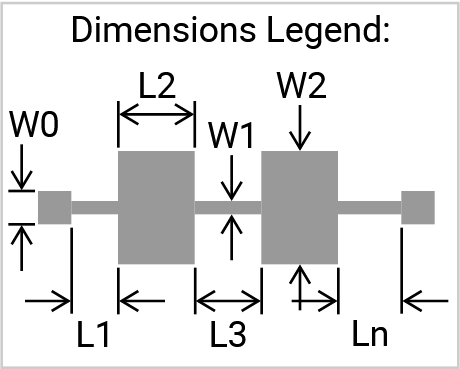

current_center = 0;
current_width = 0;
for i = 1:length(lengths)
    current_center = current_center + lengths(i)/2;
    if i == 1 || i == length(lengths)
        current_width = W0*1e-3;
    elseif mod(i, 2) == 1
        current_width = W1*1e-3;
    else
        current_width = W2*1e-3;
    end
    if i == 1
        filter = traceRectangular(Length = lengths(i), Width = current_width, Center = [current_center 0]);
    else
        filter = filter + traceRectangular(Length = lengths(i), Width = current_width, Center = [current_center 0]);
    end
    current_center = current_center + lengths(i)/2;
end

show(filter);
met = metal('copper');
met.Thickness = 18e-06; % 1/2 oz copper (18um)
sub = dielectric(EpsilonR = 3.48, LossTangent = 0.0037, Name = "RO4350B", Thickness = 0.76e-3);
gnd = traceRectangular(Length = L_tot, Width = W_tot, Center = [L_tot/2,0]);

pcb = pcbComponent(Conductor=met);
pcb.BoardShape = gnd;
pcb.BoardThickness = 0.76e-3;
pcb.Layers ={filter,sub,gnd};
pcb.FeedDiameter = W0/2*1e-3;
pcb.FeedLocations = [0 0 1 3;L_tot 0 1 3];
figure; 
show(pcb);
spar = sparameters(pcb,linspace(1e6,17e9,400));
figure
rfplot(spar,2, 1);
legend(Location="southwest")

Custom filter generation:

Procedural filter test

clc
clear all
close all

fc = 1.5e9; %1,5 GHz

% Meas in mm
LMS = 5; % 50ohm microstrip length (to connect the circuit)


% 0.5 dB ripple chebishew 10
gs = [1 1.7543 1.2721 2.6754]



% In m
lengths = [LMS, L1, L2, L3, L4, L5, L6, L7, L8, L9, L10, L11, L12, L13, LMS] * 1e-3;
L_tot = sum(lengths);
W_tot = 30e-3;

current_center = 0;
current_width = 0;
for i = 1:length(lengths)
    current_center = current_center + lengths(i)/2;
    if i == 1 || i == length(lengths)
        current_width = W0*1e-3;
    elseif mod(i, 2) == 1
        current_width = W1*1e-3;
    else
        current_width = W2*1e-3;
    end
    if i == 1
        filter = traceRectangular(Length = lengths(i), Width = current_width, Center = [current_center 0]);
    else
        filter = filter + traceRectangular(Length = lengths(i), Width = current_width, Center = [current_center 0]);
    end
    current_center = current_center + lengths(i)/2;
end

show(filter);
met = metal('copper');
met.Thickness = 18e-06; % 1/2 oz copper (18um)
sub = dielectric(EpsilonR = 3.48, LossTangent = 0.0037, Name = "RO4350B", Thickness = 0.76e-3);
gnd = traceRectangular(Length = L_tot, Width = W_tot, Center = [L_tot/2,0]);

pcb = pcbComponent(Conductor=met);
pcb.BoardShape = gnd;
pcb.BoardThickness = 0.76e-3;
pcb.Layers ={filter,sub,gnd};
pcb.FeedDiameter = W0/2*1e-3;
pcb.FeedLocations = [0 0 1 3;L_tot 0 1 3];
figure; 
show(pcb);
spar = sparameters(pcb,linspace(1e6,17e9,20));
figure
rfplot(spar,2, 1);
legend(Location="southwest")